# Chapter 1

% create different types of matrices
z = zeros(5, 5)

z =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


class(z) % type of z

ans = 'double'


z = zeros(5, 5, 'uint16')

z = 5×5 uint16 matrix
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0


class(z)

ans = 'uint16'


i = eye(5, 5) % identity matrix

i =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1



one = ones(5, 5, 3)  % 5x5x3 ones matrix

one = one(:,:,1) =

     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


one(:,:,2) =

     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


one(:,:,3) =

     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1



[r, c, ch] = size(one)  % shape of matrix

r = 5

c = 5

ch = 3

fprintf("rows = %d, cols = %d, channels = %d\n", r, c, ch) % printing to screen

rows = 5, cols = 5, channels = 3



r = randn(5, 5, 3)  % normally distributed random numbers

r = r(:,:,1) =

    0.3695    0.2760   -0.6201    1.4470    0.0953
   -0.6186    0.9842    0.2241    0.5958    1.6145
    0.8001    0.9931   -0.4661    2.0533    0.5013
    0.4267    0.6682   -0.3321   -1.5293   -0.3238
   -0.4723   -0.0650    0.9248    0.0227    0.5542


r(:,:,2) =

    0.6424    0.1095    1.9172    0.3745    2.0475
    0.1826   -1.5513    0.7784   -2.3705   -0.3237
   -2.0275   -0.3551   -0.2465    0.6151   -0.9805
    1.0231    1.3986   -0.9035    0.2795    1.1796
   -3.4915   -0.5135   -0.4959    0.8189    0.8946


r(:,:,3) =

   -0.1429   -0.6379   -1.0864    1.0235   -0.5474
   -0.5935   -0.8193    0.2403   -2.1154   -1.6510
    0.2489    0.9680   -1.0462    0.6817    0.8928
   -1.1298    0.0303    0.6187    0.0087   -0.5071
    0.0661    1.3511    1.3050    0.3343   -0.3298



mn = mean(r, "all")  % mean of all elements

mn = 0.0572

mn_cols = mean(r)  % mean of each column

mn_cols = mn_cols(:,:,1) =

    0.1011    0.5713   -0.0539    0.5179    0.4883


mn_cols(:,:,2) =

   -0.7342   -0.1824    0.2099   -0.0565    0.5635


mn_cols(:,:,3) =

   -0.3102    0.1784    0.0063   -0.0134   -0.4285



sd = std(r, [], "all")  % std of all values

sd = 1.0415

sd = std(r)  % row vector with std of each column

sd = sd(:,:,1) =

    0.6151    0.4610    0.6331    1.3841    0.7223


sd(:,:,2) =

    1.9429    1.0722    1.1384    1.3106    1.2107


sd(:,:,3) =

    0.5555    0.9595    1.0510    1.2347    0.9042




x = [1, 2, 3, NaN;
    NaN, 5, 5, 5;
    9, 0, NaN, 0]

x =      1     2     3   NaN
   NaN     5     5     5
     9     0   NaN     0


% replace NaN values with -1 using logical indexing
x(isnan(x)) = -1

x =      1     2     3    -1
    -1     5     5     5
     9     0    -1     0


% plot as image
r = randi(11, 11, 3)

r =      7     5     6
    11     4     1
     6    11     1
    11     8     2
     3     5    10
     5     2     6
     8     9     7
     1     8     6
     9     1     1
     5     2    10


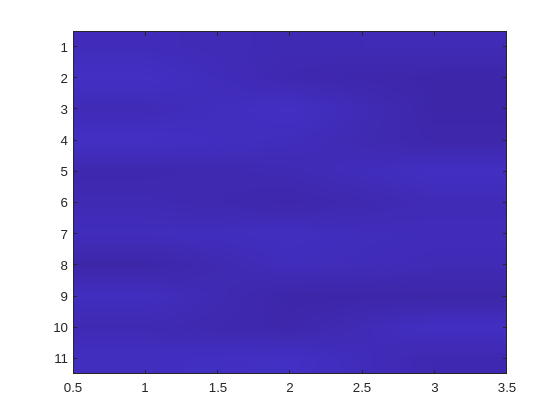

image(r, "Interpolation","bilinear")

r_1_7 = randi(7, [5, 9])  % random integers between 1 and 7, 5x9

r_1_7 =      2     7     1     1     5     6     4     3     6
     5     5     7     7     3     1     2     6     2
     4     2     5     4     1     7     2     1     1
     3     2     2     4     4     6     6     5     4
     5     4     4     4     1     7     7     4     5


r_11_21 = randi([11, 21], 7)  % 7x7 random integers between 11 and 21

r_11_21 =     12    18    15    16    11    13    11
    15    13    14    17    14    17    19
    18    19    14    16    19    21    12
    20    14    13    13    18    20    14
    14    14    21    21    12    16    15
    15    11    20    13    21    15    20
    20    15    15    20    16    14    11


m = [1:99]

m =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t = datasample(m, 5, "Replace", false)  % select 5 elements at random without repetetion

t =     84    29    25    47    70


f_handle_sum = @max  % creating a function handle

f_handle_sum = function_handle with value:
    @max


f_handle_sum(5, 7)

ans = 7

m = [1, 2, 3;
    4, 5, 6]

m =      1     2     3
     4     5     6


m .^ 2  % element wise power, same rule for all element wise operations - .<op>

ans =      1     4     9
    16    25    36


m .* [2, 0, 1]  % applies broadcasting

ans =      2     0     3
     8     0     6


fx = @(x1, x2, x3) (x1 ^ 2 + x2 ^ 3 + x3)  % using a function handle to create a function

fx = function_handle with value:
    @(x1,x2,x3)(x1^2+x2^3+x3)


fx(2, 1, 4)

ans = 9

kp_mask = [0, 0, 0, 0; ...
    0, 1, 1, 0; ...
    0, 0, 1, 1]

kp_mask =      0     0     0     0
     0     1     1     0
     0     0     1     1


one_pos = kp_mask ~= 0

one_pos = 3×4 logical array
   0   0   0   0
   0   1   1   0
   0   0   1   1


one_pos(:)

ans = 12×1 logical array
   0
   0
   0
   0
   1
   0
   0
   1
   1
   0


[r, c, v] = find(kp_mask == 1)  % find where == 1, row, col and the value (1 in this case)

r =      2
     2
     3
     3


c =      2
     3
     3
     4


v = 4×1 logical array
   1
   1
   1
   1


[r, c, v] = find(kp_mask)  % find row, col, values , where kp_mask is non-zero

r =      2
     2
     3
     3


c =      2
     3
     3
     4


v =      1
     1
     1
     1


% table arrays
m = [1, 2, 3;
    3, 4, 5;
    7, 8, 9]

m =      1     2     3
     3     4     5
     7     8     9


table(m)  % convert to a column table

ans = 3×1 table
         m     
    ___________

    1    2    3
    3    4    5
    7    8    9


array2table(m)  % adds some automatic headers for each column

ans = 3×3 table
    m1    m2    m3
    __    __    __

    1     2     3 
    3     4     5 
    7     8     9 


tab = array2table(m, "VariableNames", ["height", "width", "length"])  % specify column headers

tab = 3×3 table
    height    width    length
    ______    _____    ______

      1         2        3   
      3         4        5   
      7         8        9   


tab.width = [] % delete a column

tab = 3×2 table
    height    length
    ______    ______

      1         3   
      3         5   
      7         9   


carray = cell(5, 5)  % create 5x5 cell array

carray = 5×5 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


carray{1, 1} = 25

carray = 5×5 cell array
    {[      25]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


carray{5, 5} = linspace(1, 10, 5)  % each cell can have different datatype

carray = 5×5 cell array
    {[      25]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double                 }
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double                 }
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double                 }
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double                 }
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {[1 3.2500 5.5000 7.7500 10]}


carray{2, 2} = ['a', 'b']

carray = 5×5 cell array
    {[      25]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double                 }
    {0×0 double}    {'ab'      }    {0×0 double}    {0×0 double}    {0×0 double                 }
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double                 }
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double                 }
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {[1 3.2500 5.5000 7.7500 10]}


carray{5, 5}(1) = -1

carray = 5×5 cell array
    {[      25]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double                  }
    {0×0 double}    {'ab'      }    {0×0 double}    {0×0 double}    {0×0 double                  }
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double                  }
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double                  }
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {[-1 3.2500 5.5000 7.7500 10]}


structA = struct()  % an empty struct

structA = struct with no fields.


A.name = "sambit"  % automatically creates a structure

A = struct with fields:
      name: "sambit"
       age: 31
    grades: [1 2 3 4 5 6 7 8 9 1]


A.age = 31

A = struct with fields:
      name: "sambit"
       age: 31
    grades: [1 2 3 4 5 6 7 8 9 1]


A.grades = [1: 10]

A = struct with fields:
      name: "sambit"
       age: 31
    grades: [1 2 3 4 5 6 7 8 9 10]


A.grades(end) = 1

A = struct with fields:
      name: "sambit"
       age: 31
    grades: [1 2 3 4 5 6 7 8 9 1]


compl = 5 + 10j  % creating a complex number, avoid using i and j as other variables

compl = 5.0000 +10.0000i

abs(compl)  % magnitude of complex number

ans = 11.1803

rad2deg(angle(compl))  % phase of complex number

ans = 63.4349

help sum

 sum Sum of elements.
    S = sum(X) is the sum of the elements of the vector X. If X is a matrix,
    S is a row vector with the sum over each column. For N-D arrays, 
    sum(X) operates along the first non-singleton dimension.
 
    S = sum(X,"all") sums all elements of X.
 
    S = sum(X,DIM) sums along the dimension DIM.
 
    S = sum(X,VECDIM) operates on the dimensions specified in the vector 
    VECDIM. For example, sum(X,[1 2]) operates on the elements contained in
    the first and second dimensions of X.
 
    S = sum(...,OUTTYPE) specifies the type in which the 
    sum is performed, and the type of S. Available options are:
 
    "double"    -  S has class double for any input X
    "native"    -  S has the same class as X
    "default"   -  If X is floating point, that is double or single,
                   S has the same class as X. If

help std

 std Standard deviation.
    For vectors, Y = std(X) returns the standard deviation.  For matrices,
    Y is a row vector containing the standard deviation of each column.  For
    N-D arrays, std operates along the first non-singleton dimension of X.
 
    std normalizes Y by N-1 if N>1, where N is the sample size.  This is
    the sqrt of an unbiased estimator of the variance of the population
    from which X is drawn, as long as X consists of independent,
    identically distributed samples. For N=1, Y is normalized by N.
 
    Y = std(X,1) normalizes by N and produces the square root of the second
    moment of the sample about its mean.  std(X,0) is the same as std(X).
 
    Y = std(X,W) computes the standard deviation using the weight vector W.
    W typically contains either counts or inverse variances.  The length of
    W must equal the lengt